### ***2.2 - Signal generation and data saving***

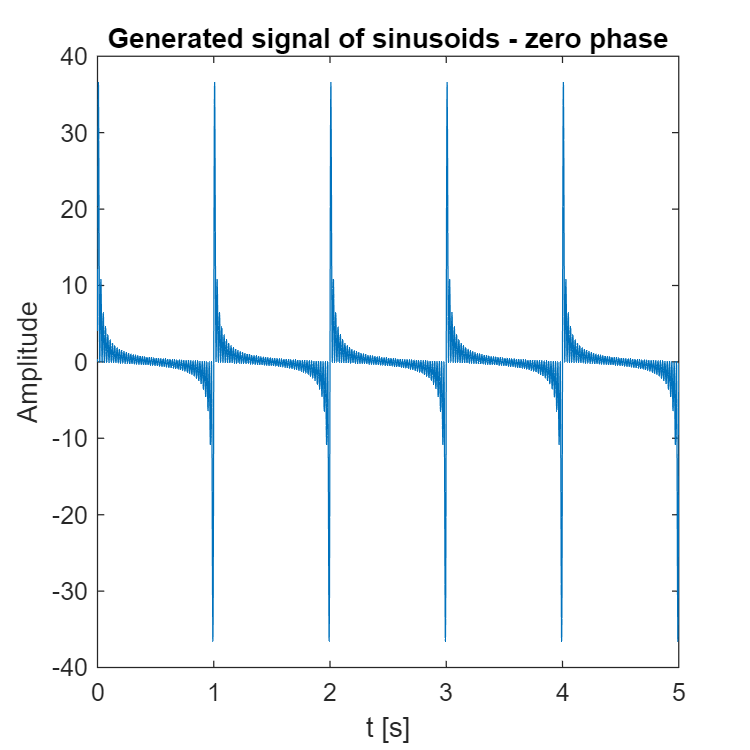

clear;
close all
a_k = 1;
f_0 = 1000;
f_s = 44100;
T = 5;
N = 50;
t = 0:(1/f_s):(T-1/f_s);

%Initializing sampling vector with f_s * T zero-values
s1 = zeros(1,f_s * T);

%% Zero phase
phase = zeros(1,N);

for k = 1:N
   s1 = s1 + a_k * sin(2*pi*k*t + phase(k));
end

figure('Name','Generated signal 1','Position',[400 300 400 400])
plot(t,s1)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - zero phase')

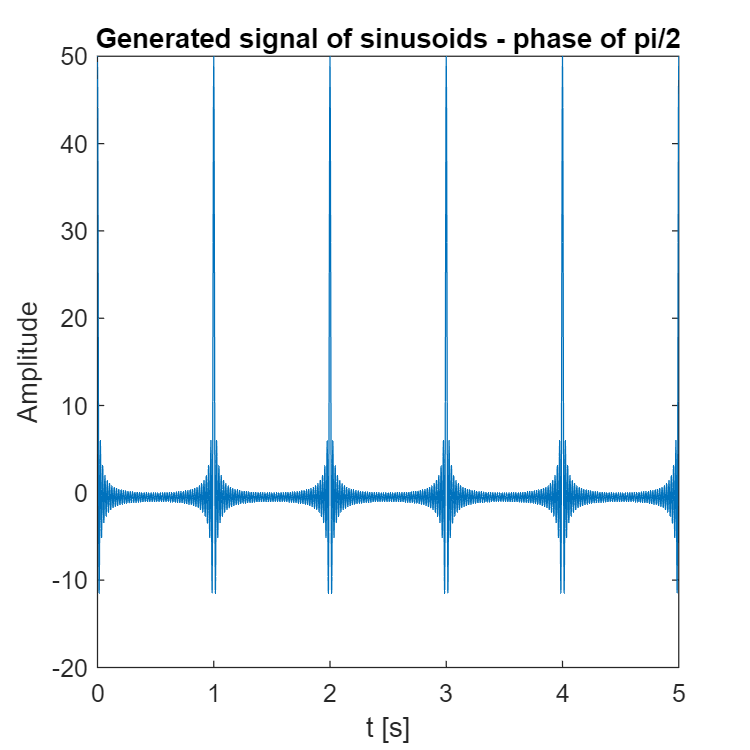

%% Phase of pi/2
s2 = zeros(1,f_s * T);
phase = pi/2;

for k = 1:N
   s2 = s2 + a_k * sin(2*pi*k*t + phase);
end

figure('Name','Generated signal 2','Position',[400 300 400 400])
plot(t,s2)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - phase of pi/2')

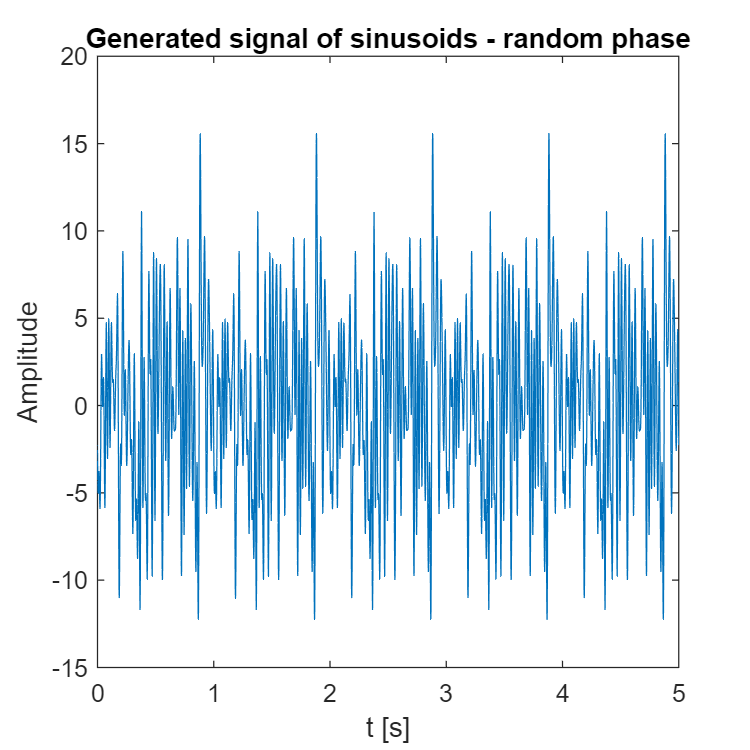

% Random phase
s3 = zeros(1,f_s * T);
%rand() generates between 0 and 1. This range is scaled by the desired
%range and the lower limit is added as an offset. In this case, it is 0.
phase = (rand(1,N) * (2*pi - 0) + 0);

for k = 1:N
    
   s3 = s3 + a_k * sin(2*pi*k*t + phase(k));
end

figure('Name','Generated signal 2','Position',[400 300 400 400])
plot(t,s3)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - random phase')

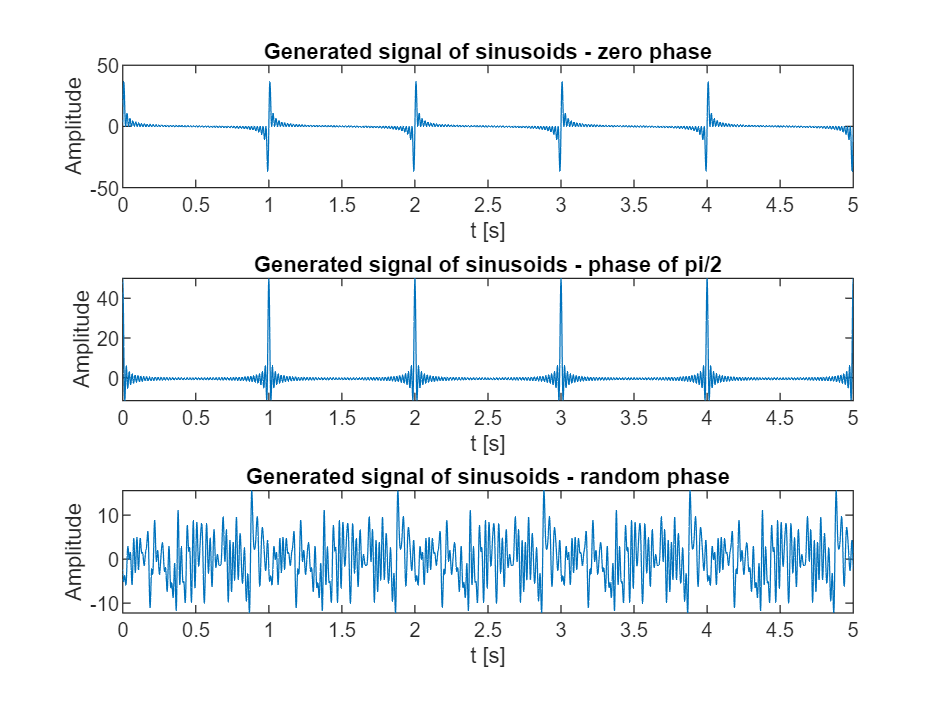


% Is there a limit of N to be considered?
% Yes, N should not cause the frequency of the element to go
% above the nyquist frequency of fs/2!

figure(99)
subplot(3,1,1)
plot(t,s1)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - zero phase')
subplot(3,1,2)
plot(t,s2)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - phase of pi/2')
subplot(3,1,3)
plot(t,s3)
xlabel('t [s]'), ylabel('Amplitude')
title('Generated signal of sinusoids - random phase')